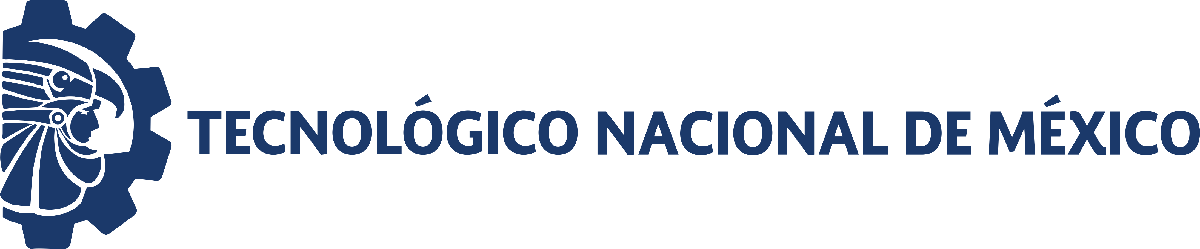                                 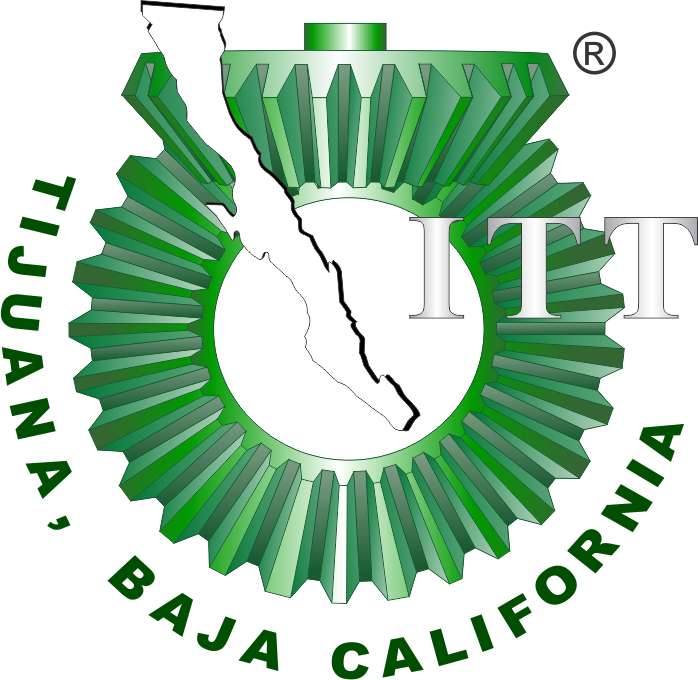

# Práctica 2: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

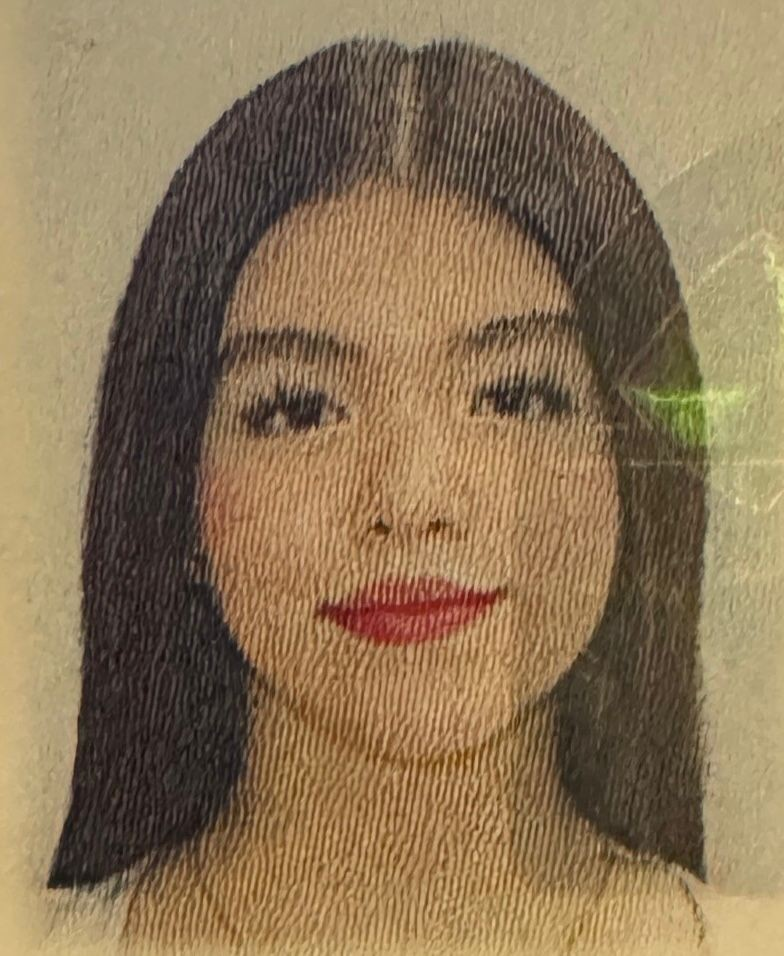

Nombre del alumno: **Angelica Ashia Haro Najar**

Número de control: **23210708**

Correo institucional: **l23210708@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc;
clear;
close all;
warning('off','all');

tend = '10';
file = 'Sistema2';

open_system(file);

parameters.StopTime = '15';
parameters.Solver   = 'ode15s';
parameters.MaxStep  = '1E-3';
x = sim(file,parameters);
writematrix(x.Pa,'signal.xlsx')

set_param('Sistema2/Vs0(t)','VectorFormat','1-D array');

## Respuesta del sistema 

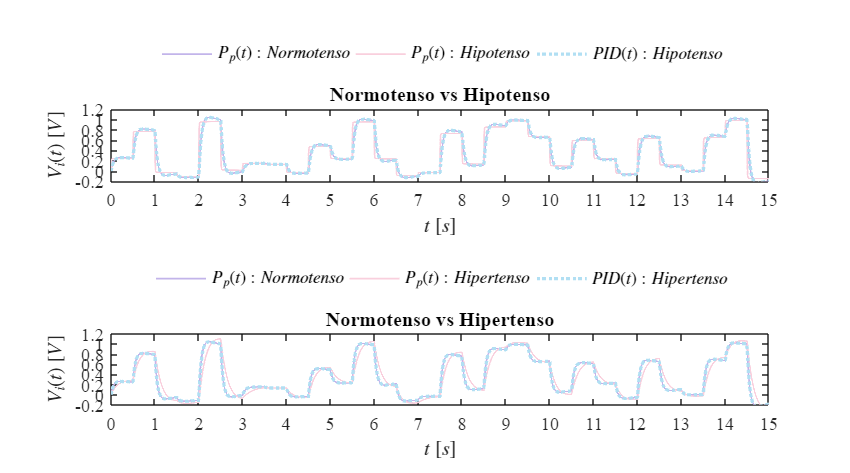

plotsignals(x.t,x.Pp1,x.Pp2,x.Pp3,x.PID1,x.PID2)

## Función: Respuesta a las señales

function plotsignals(t,Pp1,Pp2,Pp3,PID1,PID2)
    figure('Color','w')
    set(gcf,'Units','centimeters','Position',[1,1,18,10])

    colors = [194, 180, 234;
              249, 207, 221;
              177, 223, 243]/255;
    colororder(colors)

    subplot(2,1,1); box on; hold on;
    P = plot(t,Pp1,'-',t,Pp2,'-',t,PID1,':','LineWidth',1);
    set(P(3),'LineWidth',2)
    L = legend('$P_p(t):Normotenso$','$P_p(t):Hipotenso$','$PID(t):Hipotenso$');
    set(L,'Interpreter','latex','FontSize',10,'Location',...
        'northoutside','Box','off','Orientation','horizontal')
    xlabel('$t$ $[s]$','Interpreter','latex','FontSize',11)
    ylabel('$V_i(t)$ $[V]$','Interpreter','latex','FontSize',11)
    xlim([0,15]); xticks(0:1:15)
    ylim([-0.2,1.2]); yticks(-0.2:0.2:1.2)
    title('Normotenso vs Hipotenso','FontSize',10)
    set(gca,'FontName','Times New Roman','FontSize',11)

    subplot(2,1,2); box on; hold on;
    P = plot(t,Pp1,'-',t,Pp3,'-',t,PID2,':','LineWidth',1);
    set(P(3),'LineWidth',2)
    L = legend('$P_p(t):Normotenso$','$P_p(t):Hipertenso$','$PID(t):Hipertenso$');
    set(L,'Interpreter','latex','FontSize',10,'Location',...
        'northoutside','Box','off','Orientation','horizontal')
    xlabel('$t$ $[s]$','Interpreter','latex','FontSize',11)
    ylabel('$V_i(t)$ $[V]$','Interpreter','latex','FontSize',11)
    xlim([0,15]); xticks(0:1:15)
    ylim([-0.2,1.2]); yticks(-0.2:0.2:1.2)
    title('Normotenso vs Hipertenso','FontSize',10)
    set(gca,'FontName','Times New Roman','FontSize',11)

    exportgraphics(gcf,'Cardiovascular.pdf','ContentType','vector')
end
